n=5;
[bestindv,bestresult,Results,meanGAesVar,stdGAesVar,BestHistory,CurrentHistory,Step]...
    = fGAmultiLine(7,n,100,50,45,7,8,5,TR_DATA);

Elapsed time is 83.756507 seconds.


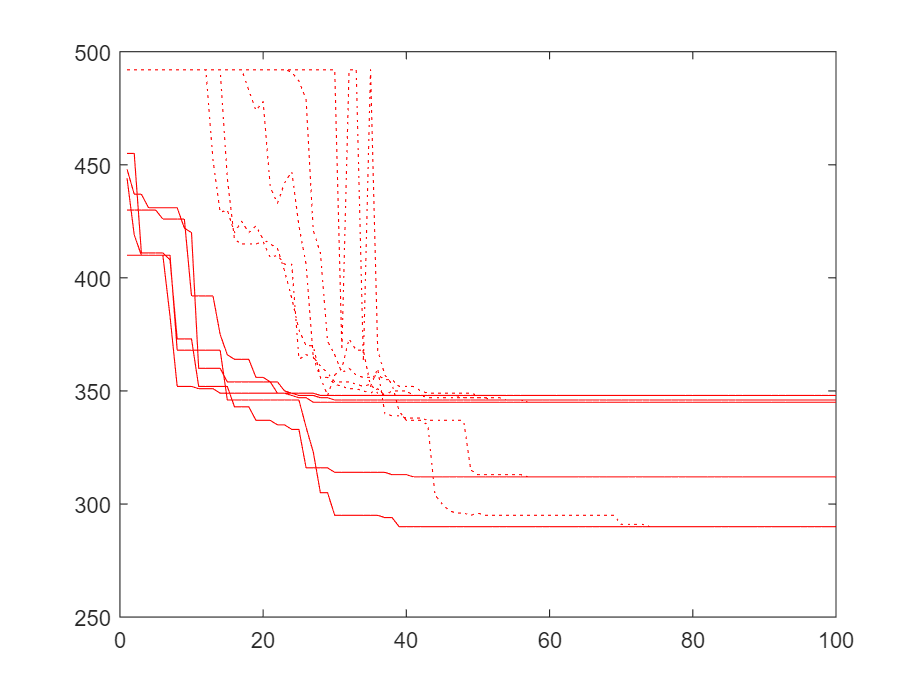


figure(1);
xlabel('Iteration number');
    ylabel('Objective function value');
for i=1:n

 plot(BestHistory(i,:),'Color','r'); hold on      
   plot(CurrentHistory(i,:),'Color','r','LineStyle',':'); 
   
    
end

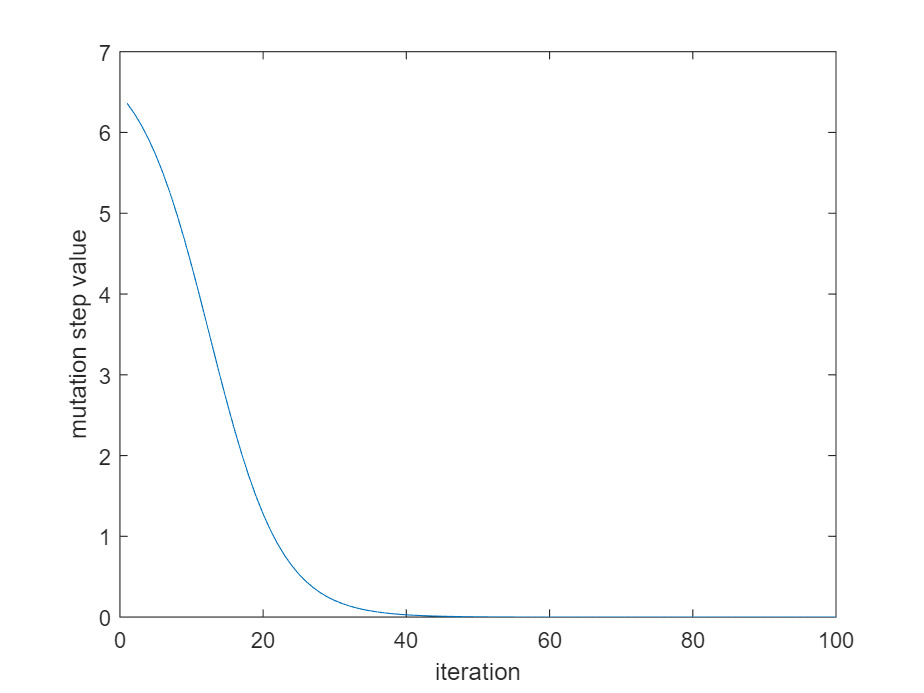


figure(2);
plot(Step(1,:))
xlabel('iteration');
ylabel('mutation step value');


disp('best indv cost>>');disp(bestresult);

best indv cost>>
   290



disp('results>>');disp(bestindv)

results>>
  1×5 struct array with fields:

    OF
    Parameters



c=zeros(n,1);
for i=1:n
    c(i,1)=fcost(bestindv(n).Parameters(1),bestindv(n).Parameters(2),VA_DATA);
end

Index exceeds the number of array elements. Index must not exceed 1.

disp(c);
histogram(c)